# A Simple Mobile Telephony Cell

**Assumptions**: A square region, surrounding a cell tower, is divided into a grid. The LOS/NLOS RF propagation model is used to predict the median received power at each grid location.

**Parameters**: All parameters of the RF propagation model, such as antenna height and frequency. Grid size (side, in meters) and number of divisions (resolution). In addition, the user may select the transmitted power, the noise PSD (in the range from 1 nW to 1 μW), the link bit rate and the constellation used (BPSK, QPSK, QAM-16, 32, and 256), and the path loss exponent β. Most parameters should be specified by the user with GUI controls.

In addition, the height of obstacles (in meters) is specified in a matrix of the same size as the grid. The user may select among the following terrain types: flat; random small hills (up to 2 meters), random large hills (up to 5 m), and mountain (one large mountain covering an entire section of the grid).

**Output**: If any of the input parameters is outside the valid range, the output should be an error message.

Assuming valid parameters, the output must be two different heatmap plots (a heatmap is a matrix plotted in 2-D, where the value of each matrix element is represented as a color). The first heatmap must show the received power. The second heatmap shows the BER at each location.

The received power is calculated according to the free-space loss equation (with path loss exponent β), in the case of LOS. When the link is NLOS, the loss increases by 30 dB.

clearvars
clc;
clear all;
close all;

## User-defined input

% Propagation model parameters
Gt = 20;   % Transmitter antenna gain
Tx_ht = 4;  % Tx antenna height
Gr = 2;    % Receiver antenna gain
freq = 750*10^6;  % frequency (700-800 MHz)
Ptx = 1;    % Transmitted power (W)
N_psd = 0.501*10^-6;    % Noise power spectral density (1nW - 1uW)
beta = 2;     % Path Loss exponent 
                                      % 1-2 : urban areas
                                      % 3-5 : microcells

% Grid parameters
g_lt = 15;  % Grid length and width (Assumed to be same)
% g_wt = 15;  % Grid width
g_res_x_y = 5; % Ensuring same number of grids in both x, and y-side
% g_res_y = 3;    % Number of grids in y - side

% Can show the grid here, and ask for the gNB location initially
% Assumption-1: For now, I will assume a fixed location for the gNB

% Assumption-2: Number of grids in x- and y- direction are same, to
% calculate the Tx-Rx distance easily. (Will modify later)

% obs_ht =  
terrain = 3;    % 1 - flat; 
                                        % 2 - small hill (2m) 
                                        % 3 - large hill (5 m)
                                        % 4 - mountain (10 m)
                                        % Note: Later try to put all the
                                        % terrain types in a single cell
                                        % tower region

% Modulation parameters
N = 10;   % Number of transmitted bits
R = 50*10^6;    % Link rate (Mbps)
Constellation = 1;    % 1 - BPSK; 
                                             % 2 - QPSK 
                                             % 3 - QAM-16
                                             % 4 - QAM-32
                                             % 5 - QAM-256
fc = 2*10^3;  % Modulating signal carrier frequency
fs = 100*10^3;  % Sampling frequency
ts = 1/fs;  % Sampling period
bit_rate = 1*10^3;    % bit rate
Ac = 1;  % Carrier amplitude
T = 1;  % pulse interval or time period, and Symbol period = 1/T

beta_srrc = 0.5 ;   % SRRC pulse excess bandwidth
phi = 4.7; % Transmitter carrier frequency phase

## Transmitter model

% [BPSK_signal, data_bits, t_index] = bpsk_mod(N,fs, bit_rate, Ac, fc);
% 
% figure(1)
% subplot(2,1,1)
% plot(t_index*1000, data_bits);
% subplot(2,1,2)
% plot(t_index*1000,BPSK_signal)
% 
% 
% % Generating SRRC pulse shape
% [p, tt] = srrcpulse(beta_srrc, T, 1/100, 10);
% figure(2)
% plot(tt,p);
% 
% bb = conv(p, BPSK_signal);  % baseband OOK signal
% 
% % Geberating carrier signal
% t = 0:ts:ts*(length(bb)-1);
% carrier = cos(2*pi*fc*t + phi);
% 
% % Transmitted signal
% tx_signal = bb.*carrier;




## Channel model

% 1. Grid matrix
% if terrain == 1
%     terrain_ht = 0; % Terraing Height in meter
% elseif terrain == 2
%     terrain_ht = 2;
% elseif terrain == 3
%     terrain_ht = 5;
% elseif terrain == 4
%     terrain_ht = 10;
% end
% g_mat = terrain_ht*ones(g_res_x_y, g_res_x_y); % Assigning same terrain height to all the grids
% g_mat(1,1) = Tx_ht; % Assigning the 1x1 grid to Tx antenna height.
% fprintf('Size of terrain in each grid (in meters):') , g_mat

% g_mat_tmp = ones(g_res_x_y,g_res_x_y)
terrain_ht = [0, 2, 5, 10];
terrain_idx = randi(4,g_res_x_y,g_res_x_y);

g_mat = terrain_ht(terrain_idx) % grid matrix with various terrain heights

g_mat =     10     0     0     0     5
    10     2    10     2     0
     0     5    10    10    10
    10    10     2    10    10
     5    10    10    10     5



% Tx_loc = g_mat(g_res_x_y/2+0.5,g_res_x_y/2+0.5);
g_mat(g_res_x_y/2+0.5,g_res_x_y/2+0.5) = Tx_ht      % Putting the gNB antenna in the middle

g_mat =     10     0     0     0     5
    10     2    10     2     0
     0     5     4    10    10
    10    10     2    10    10
     5    10    10    10     5






% Extracting part of a matrix efficiently
% xx = magic(5)
% yy1 = xx(1:3,3:4)


% ********************************************************************************************************************
% 2. LOS/nLOS extraction (1 -> LOS; 2 -> nLOS)

state_mat = LOS_nLOS(g_mat);
fprintf('LOS(1) or nLOS(2) condition in each grid:'), state_mat

LOS(1) or nLOS(2) condition in each grid:

state_mat =      2     2     2     2     2
     2     2     2     2     2
     2     2     2     2     2
     2     2     2     2     2
     2     2     2     2     2



% ********************************************************************************************************************
% 3. Eucledian distance between the Tx and each grid
[row, col] = size(g_mat); 
tmp_lt = g_lt/g_res_x_y;

% dist_mat = tmp_wd*ones(tmp_lt,tmp_wd);
% dist_mat = 0:tmp_lt:g_lt,0:tmp_lt:g_lt
% dist_mat(1,1) = 0

% The original distance is the hypotenuse (Eucledian) in the matrix
% [row2,col2] = size(dist_mat);
% Euclid_Dist = zeros(row2,col2);
% for idx3 = 1 : row2 
%   for idx4 = 1 : col2
%       Euclid_Dist(idx3, idx4) = sqrt((dist_mat(idx3, 1) - dist_mat(idx4, 1)) ^ 2 + ...
%                         (dist_mat(idx3, 2) - dist_mat(idx4, 2)) ^ 2);
%   end     
% end
% Euclid_Dist

% creating an initial distance matrix
dist_mat = zeros(row,col);
tmp2=0;
for idx1 = 1:row
    tmp1=0;
    
    for idx2 = 1:col
        dist_mat(idx1,idx2) = tmp1 + tmp2;
        tmp1 = tmp1 + tmp_lt;
    end
    tmp2 = tmp2 + tmp_lt;
end
dist_mat

dist_mat =      0     3     6     9    12
     3     6     9    12    15
     6     9    12    15    18
     9    12    15    18    21
    12    15    18    21    24



% Extracting the eucledian distance 
% Accurate distance for the nLOS paths in the grid
Euclid_Dist = dist_mat;
mid = g_res_x_y/2+0.5

mid = 3

for idx1 = 1:mid-1
    for idx2 = 1:mid-1
        Euclid_Dist(idx1,idx2) = sqrt((dist_mat(idx1,idx2)-dist_mat(mid,idx2))^2+(dist_mat(mid,idx2)-dist_mat(mid,mid))^2);

    end
end
% Euclid_Dist

for idx1 = 1:mid-1
    for idx2 = mid+1:g_res_x_y
        Euclid_Dist(idx1,idx2) = sqrt((dist_mat(idx1,idx2)-dist_mat(mid,idx2))^2+(dist_mat(mid,idx2)-dist_mat(mid,mid))^2);

    end
end
% Euclid_Dist

for idx1 = mid+1:g_res_x_y
    for idx2 = 1:mid-1
        Euclid_Dist(idx1,idx2) = sqrt((dist_mat(idx1,idx2)-dist_mat(mid,idx2))^2+(dist_mat(mid,idx2)-dist_mat(mid,mid))^2);

    end
end
% Euclid_Dist

for idx1 = mid+1:g_res_x_y
    for idx2 = mid+1:g_res_x_y
        Euclid_Dist(idx1,idx2) = sqrt((dist_mat(idx1,idx2)-dist_mat(mid,idx2))^2+(dist_mat(mid,idx2)-dist_mat(mid,mid))^2);

    end
end
Euclid_Dist

Euclid_Dist =     8.4853    6.7082    6.0000    6.7082    8.4853
    6.7082    4.2426    9.0000    4.2426    6.7082
    6.0000    9.0000   12.0000   15.0000   18.0000
    6.7082    4.2426   15.0000    4.2426    6.7082
    8.4853    6.7082   18.0000    6.7082    8.4853



% Accurate distance for the LOS paths of the grid
for idx1 = 1:g_res_x_y
    Euclid_Dist(idx1,mid) = abs(dist_mat(mid,mid)-dist_mat(idx1,mid));
end
% Euclid_Dist

for idx1 = 1:g_res_x_y
    Euclid_Dist(mid,idx1) = abs(dist_mat(mid,mid)-dist_mat(mid,idx1));
end
Euclid_Dist

Euclid_Dist =     8.4853    6.7082    6.0000    6.7082    8.4853
    6.7082    4.2426    3.0000    4.2426    6.7082
    6.0000    3.0000         0    3.0000    6.0000
    6.7082    4.2426    3.0000    4.2426    6.7082
    8.4853    6.7082    6.0000    6.7082    8.4853


                                           
 
% ********************************************************************************************************************
% 4. Received power in each grid
% function [Rx] = RxPower(Pt, Gt, Gr, fc, beta, LOS, dist)
Rx_mat = zeros(row,col);
for idx1 = 1:row
    for idx2 = 1:col
        Rx_mat(idx1,idx2) = RxPower(Ptx,Gt,Gr,freq,beta,state_mat(idx1,idx2),Euclid_Dist(idx1,idx2));
    end
end
% Rx_mat(mid,mid)=0;
Rx_mat

Rx_mat = 	1.0e+-5 *

    0.0563    0.0901    0.1126    0.0901    0.0563
    0.0901    0.2252    0.4503    0.2252    0.0901
    0.1126    0.4503       Inf    0.4503    0.1126
    0.0901    0.2252    0.4503    0.2252    0.0901
    0.0563    0.0901    0.1126    0.0901    0.0563



Rx_mat_dB = 10*log10(Rx_mat)    % Received power in dBm

Rx_mat_dB =   -62.4957  -60.4545  -59.4854  -60.4545  -62.4957
  -60.4545  -56.4751  -53.4648  -56.4751  -60.4545
  -59.4854  -53.4648       Inf  -53.4648  -59.4854
  -60.4545  -56.4751  -53.4648  -56.4751  -60.4545
  -62.4957  -60.4545  -59.4854  -60.4545  -62.4957


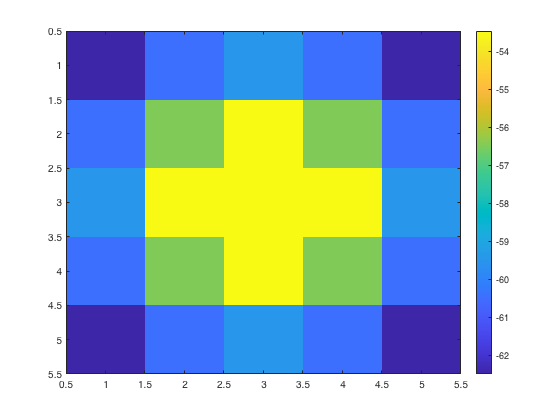

figure(1)
imagesc(Rx_mat_dB);
colorbar

% heatmap(Rx_mat)
% heatmap(Rx_mat_dB,'Colormap',redbluecmap, 'FontSize',20)

% ********************************************************************************************************************
% 5. BER in each grid
% SINR_mat = zeros(row,col);
% for idx1 = 1:row
%     for idx2 = 1:col
%         SINR_mat(idx1,idx2) = Rx_mat(idx1,idx2);
%     end
% end
% SINR_mat(1,1)=0;
% SINR_mat

BER_mat = zeros(row,col);
for idx1 = 1:row
    for idx2 = 1:col
        BER_mat(idx1,idx2) = BER_map(bit_rate,Rx_mat(idx1,idx2),N_psd,Constellation);
    end
end
BER_mat

BER_mat =     0.4811    0.4761    0.4733    0.4761    0.4811
    0.4761    0.4622    0.4467    0.4622    0.4761
    0.4733    0.4467         0    0.4467    0.4733
    0.4761    0.4622    0.4467    0.4622    0.4761
    0.4811    0.4761    0.4733    0.4761    0.4811


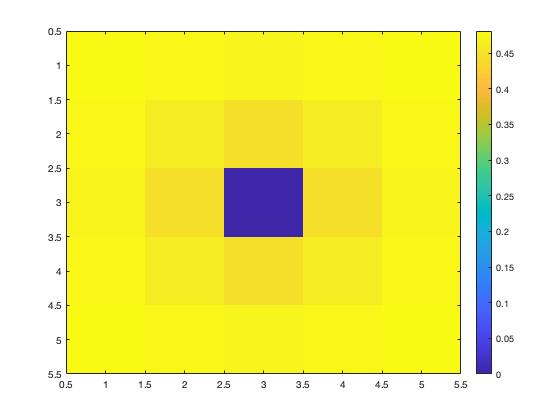


figure(2)
imagesc(BER_mat);
colorbar


% if Constellation==1 % BPSK
%     K = 1;
% % elseif Constellation==2 % QPSK
% %     K = 2;
% % elseif Constellation==3 % 16-QAM
% %     K = 4;
% % elseif Constellation==4 % 32-QAM
% %     K = 5;
% % elseif Constellation==5 % 256-QAM
% %     K = 8;
% % end
% % 
% % % Calculate symbol rate
% sym_rate = bit_rate/K
% % 
% % % Calculate symbol energy
% symb_energy = Rx_mat/sym_rate
% % 
% % % Calculate bit energy
% bit_energy = symb_energy/K
% % 
% % % Calculate SINR
% SNR_tmp = symb_energy/N_psd
% % 
% % % Calculate BER
% % if Constellation==1 % BPSK
%     BER_tmp = qfunc(sqrt(2*SNR_tmp))






                                             